# Motor Parameters

%% Inputs %%

m = 100;        % in kg, including conversion kit and rider
a = 0.5;        % desired acceleration in m.s^-2
d_in = 16:29;   % wheel diameter in inches (range between 16" and 29")
g = 9.81;       % gravitational constant
v = 15.5;       % desired velocity in mph (max 15.5)
Ac_d = 0.5;     % drag coefficient multiplied by surface Area
incl = 0;       % hill inclination in degrees
rho = 1.2;      % air density in kg.m^-3

%% Conversions %%

v_m = v/2.237;                                  % ground speeed in m.s^-1
d_m = 0.0254*d_in;                              % wheel diameter in meters
C_rr = 0.0643988./nthroot(d_in.^2*m*g/4.448,4); % coefficient of rolling resistance
theta = incl*pi/180;                            % inclination in radians

%% Forces %%

F = m*a;                    % force needed to accelerate
F_d = 0.5*Ac_d*v_m^2*rho;   % drag force
F_rr = C_rr*m*g;            % rolling resistance force (rolling friction)
F_h = m*g*sin(theta);       % force from the hill

%% Torque %%

T = (d_m/2).*(F+F_d+F_rr+F_h)

T =    13.9195   14.7630   15.6058   16.4480   17.2894   18.1304   18.9707   19.8106   20.6500   21.4889   22.3275   23.1656   24.0034   24.8408



%% RPM %%

rpm = 60*v_m./(pi*d_m)       % rotations per minute

rpm =   325.6217  306.4675  289.4415  274.2078  260.4974  248.0928  236.8158  226.5195  217.0812  208.3979  200.3826  192.9610  186.0696  179.6534



%% Power %%

P = T.*rpm/9.55              % power in Watts

P =   474.6056  473.7578  472.9817  472.2677  471.6079  470.9958  470.4260  469.8937  469.3950  468.9266  468.4855  468.0691  467.6752  467.3019



average_power = P/(1.75)

average_power =   271.2032  270.7188  270.2753  269.8672  269.4902  269.1405  268.8148  268.5107  268.2257  267.9581  267.7060  267.4680  267.2430  267.0296



%% Motor %%

peak_motor_torque = 3;      % motor peak torque 
max_motor_rpm = 2340;       % motor max rpm
diameter_motor = 0.075;     % in m

drive_efficiency = 100;                                  % in (%)
torque_motor = drive_efficiency*peak_motor_torque/100;  % in N.m-1
rpm_motor = drive_efficiency*max_motor_rpm/100;         % nominal rpm

ratio = diameter_motor ./ d_m;

delivered_torque = torque_motor ./ ratio

delivered_torque =    16.2560   17.2720   18.2880   19.3040   20.3200   21.3360   22.3520   23.3680   24.3840   25.4000   26.4160   27.4320   28.4480   29.4640


torque_diff = delivered_torque - T

torque_diff =     2.3365    2.5090    2.6822    2.8560    3.0306    3.2056    3.3813    3.5574    3.7340    3.9111    4.0885    4.2664    4.4446    4.6232


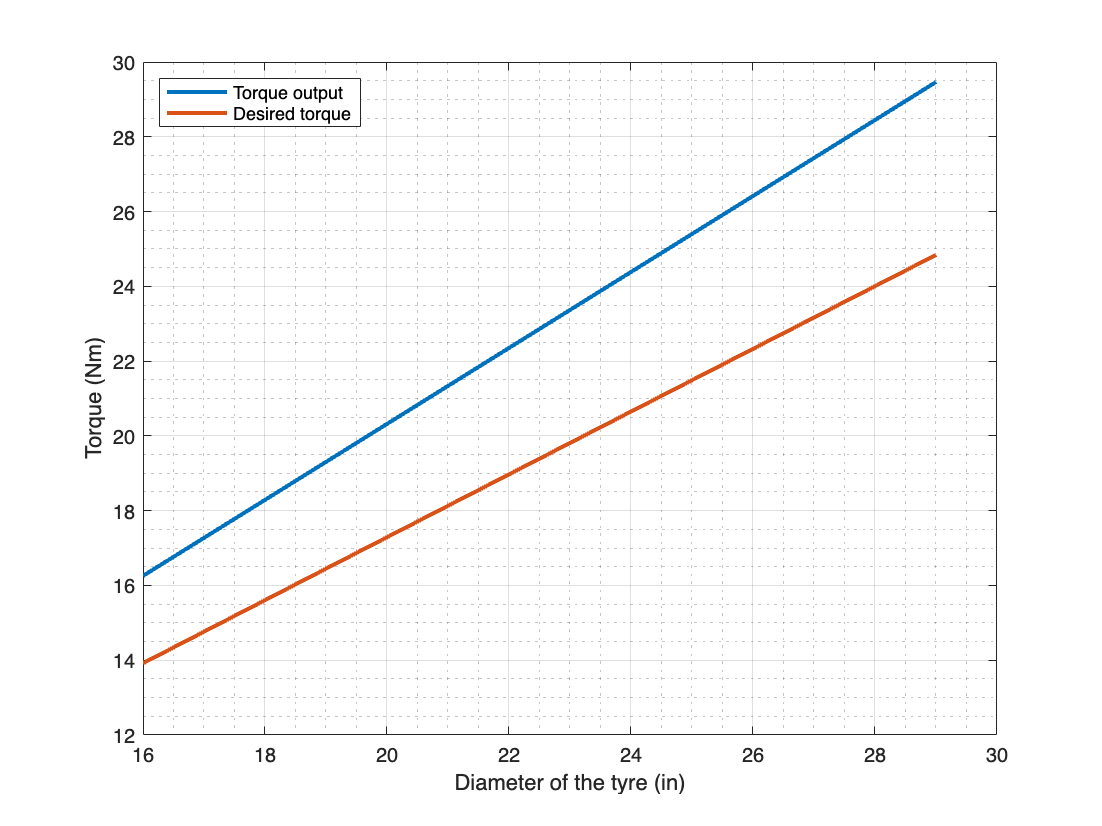

plot(d_in,delivered_torque,"LineWidth",2)
hold on
plot(d_in,T,"LineWidth",2)
xlabel("Diameter of the tyre (in)")
ylabel("Torque (Nm)")
legend("Torque output","Desired torque","Location","northwest")
grid on
grid minor
hold off


delivered_rpm = rpm_motor .* ratio

delivered_rpm =   431.8406  406.4382  383.8583  363.6552  345.4724  329.0214  314.0659  300.4108  287.8937  276.3780  265.7480  255.9055  246.7660  238.2569


rpm_diff = delivered_rpm - rpm

rpm_diff =   106.2188   99.9706   94.4167   89.4474   84.9750   80.9286   77.2500   73.8913   70.8125   67.9800   65.3654   62.9445   60.6965   58.6035


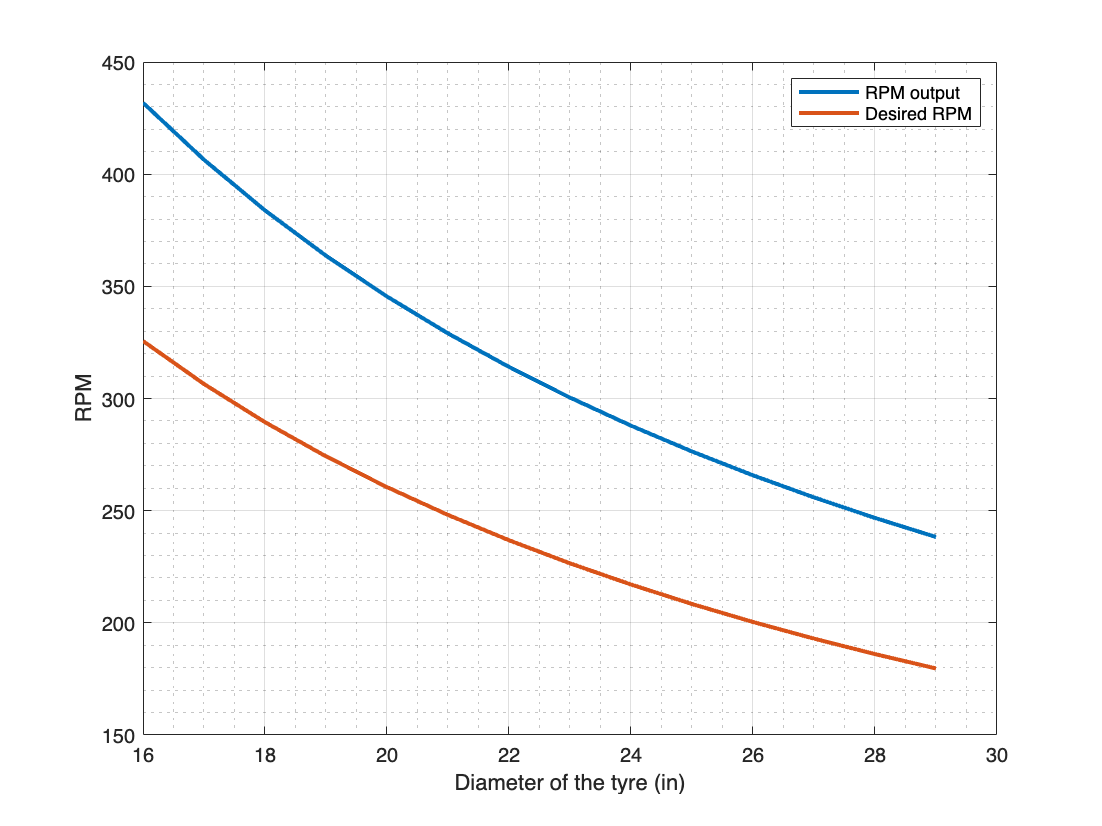

plot(d_in,delivered_rpm,"LineWidth",2)
hold on
plot(d_in,rpm,"LineWidth",2)
xlabel("Diameter of the tyre (in)")
ylabel("RPM")
legend("RPM output","Desired RPM","Location","northeast")
grid on
grid minor
hold off

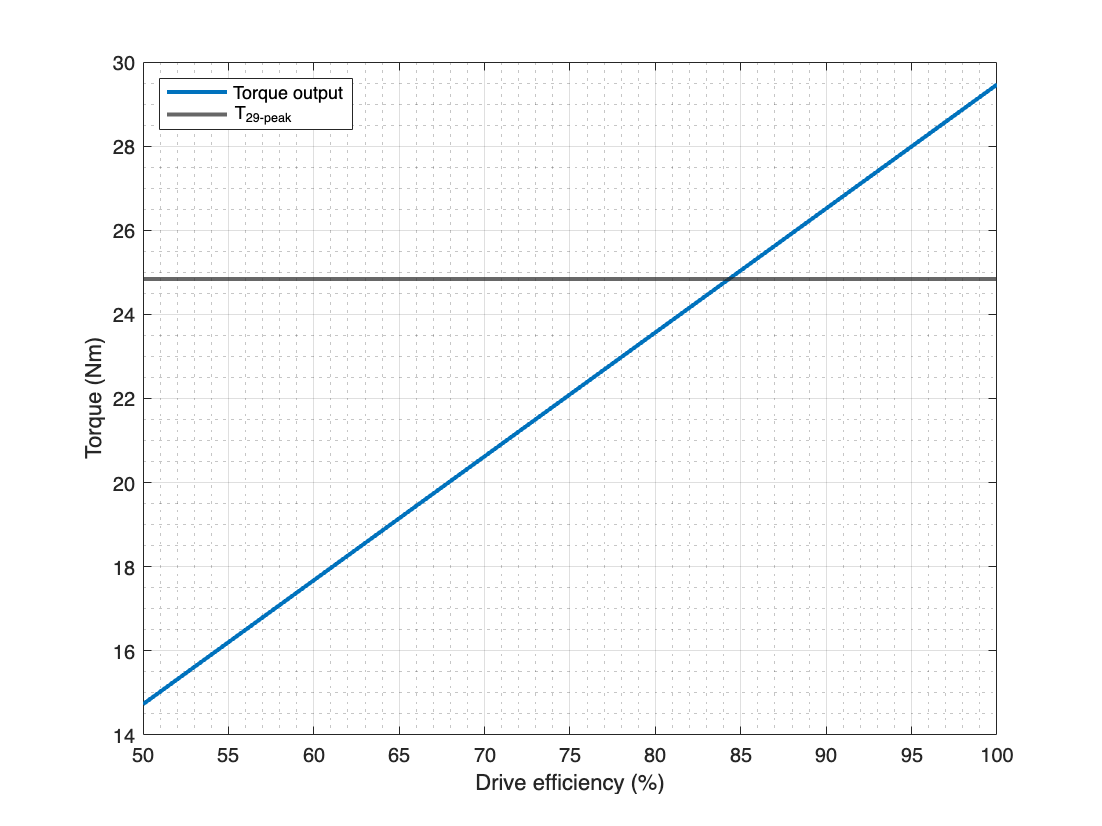


drive_friction_29_inch = 0.5:0.05:1;
torque_friction = drive_friction_29_inch*peak_motor_torque;
rpm_friction = drive_friction_29_inch*max_motor_rpm;

ratio_friction = diameter_motor/(0.0254*29);

delivered_torque_friction = torque_friction ./ ratio_friction;
plot(drive_friction_29_inch*100,delivered_torque_friction,"LineWidth",2)
hold on
yline(T(14),"LineWidth",2)
xlabel("Drive efficiency (%)")
ylabel("Torque (Nm)")
legend("Torque output","T_{29-peak}","Location","northwest")
grid on
grid minor
hold off

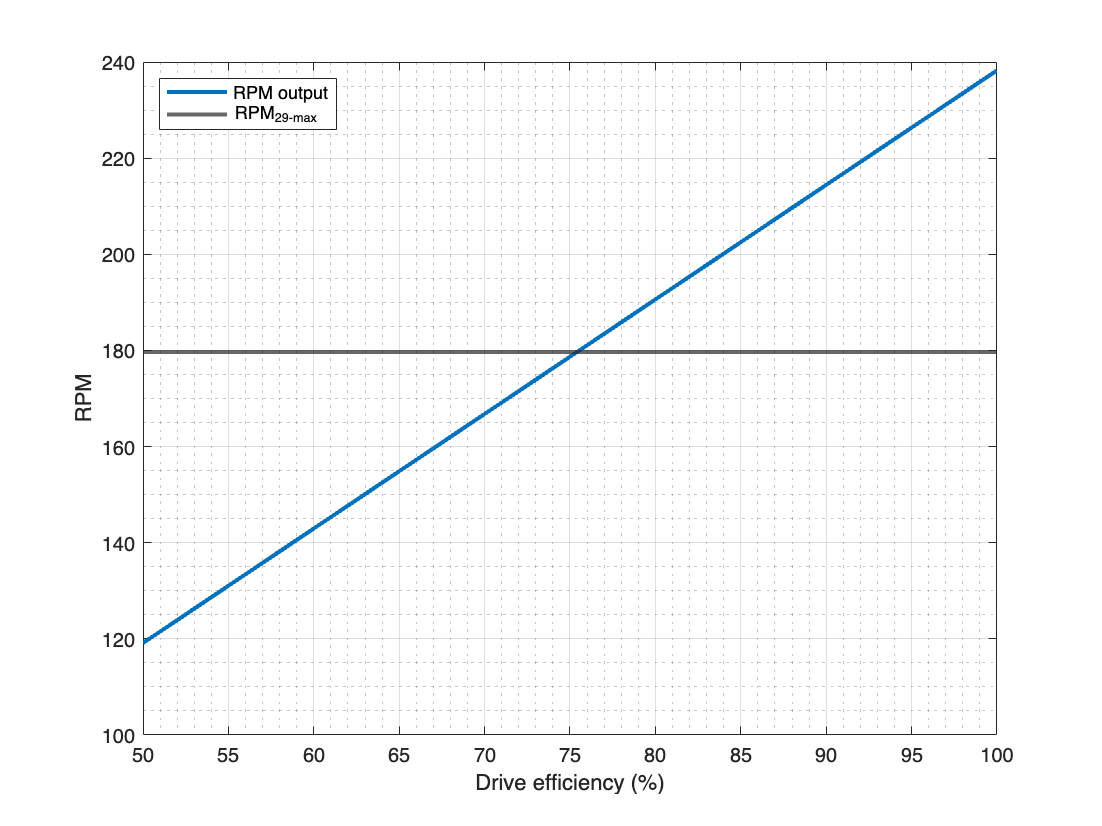


delivered_rpm_friction = rpm_friction .* ratio_friction;
plot(drive_friction_29_inch*100,delivered_rpm_friction,"LineWidth",2)
hold on
yline(rpm(14),"LineWidth",2)
xlabel("Drive efficiency (%)")
ylabel("RPM")
legend("RPM output","RPM_{29-max}","Location","northwest")
grid on
grid minor
hold off

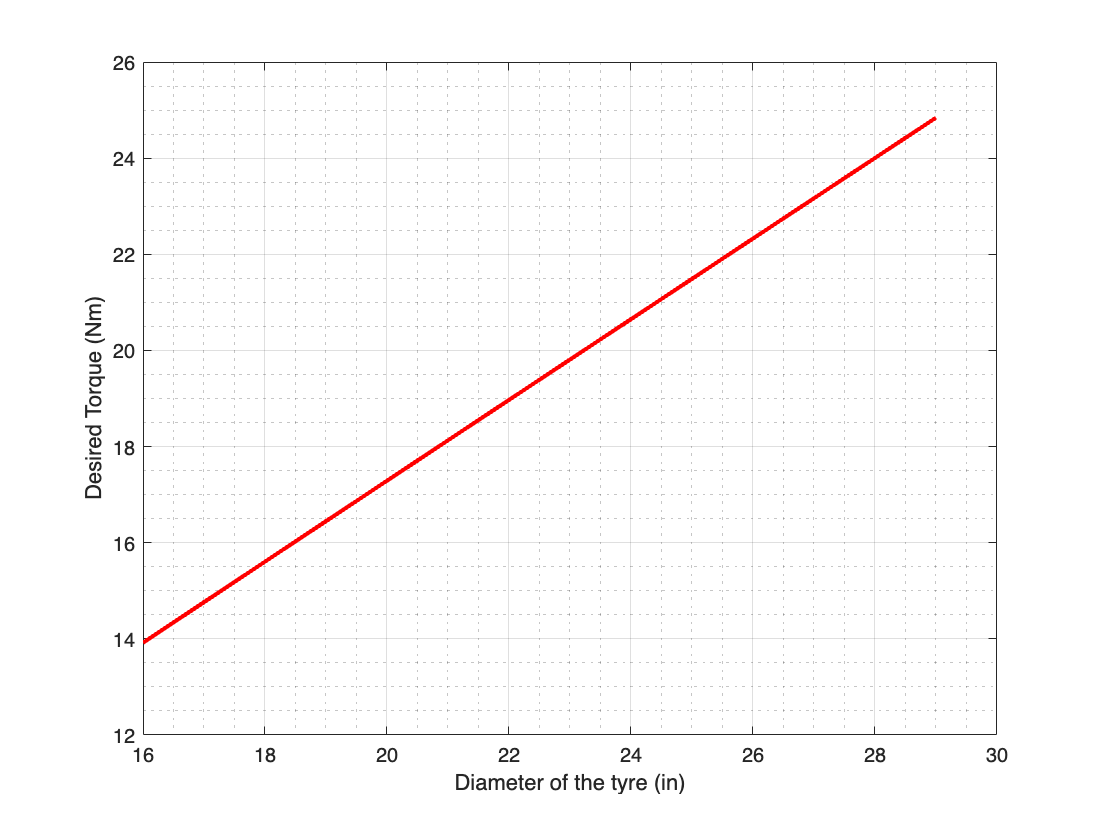



plot(d_in,T,"LineWidth",2,"Color",'r')
xlabel("Diameter of the tyre (in)")
ylabel("Desired Torque (Nm)")
grid on
grid minor

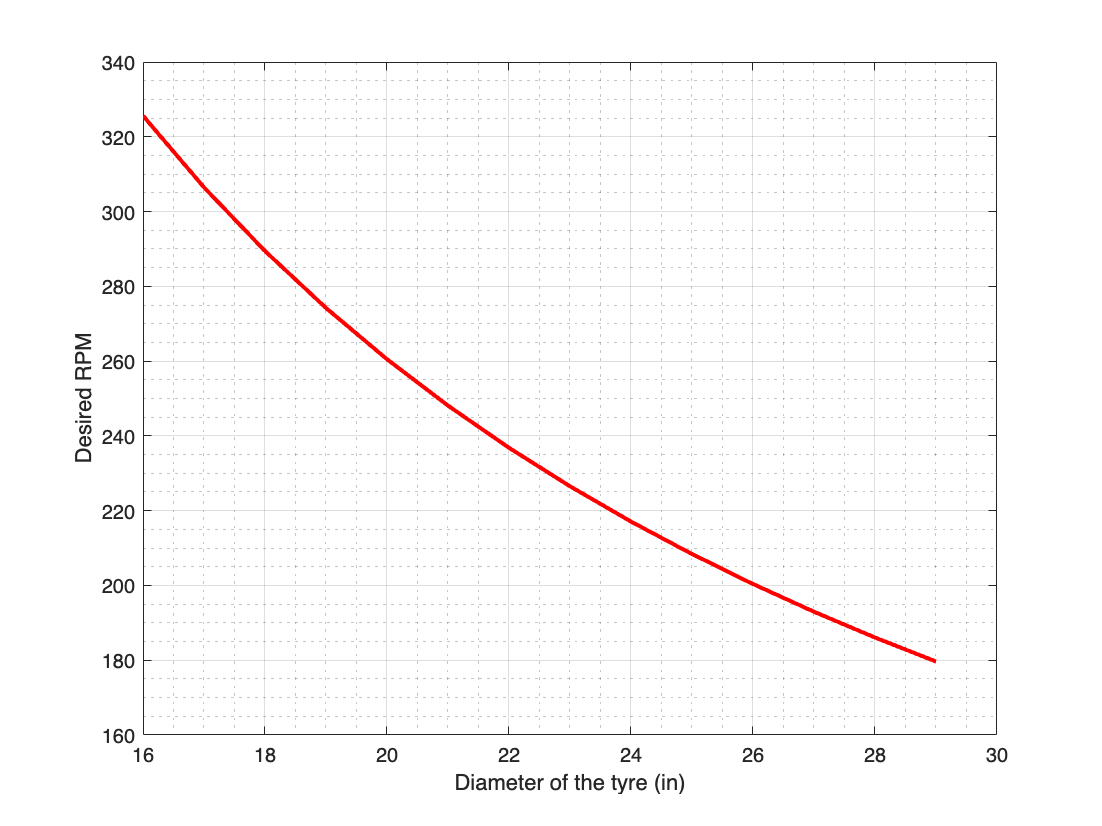


plot(d_in,rpm,"LineWidth",2,"Color",'r')
xlabel("Diameter of the tyre (in)")
ylabel("Desired RPM")
grid on
grid minor

# FORCES ON THE KIT

%% PARAMETERS %%
m_kit = 3;                  % mass of the kit in kg
g = 9.81;                   % acceleration from gravity in m.s^-2
mu_motor_wheel = 1.10;      % friction coefficient between the motor and the wheel same link as above
d_spring = 0.005;           % spring displacement in m

%% MOMENT AND FORCES ON MOTOR AND MOTOR MOUNTING %%
R_m_max = 200*peak_motor_torque/(mu_motor_wheel*diameter_motor*drive_efficiency)   % Horizontal reaction force exerted by the wheel in N

R_m_max = 72.7273

k_spring = R_m_max/d_spring                                                        % Spring constant needed to keep equilibrium in N.m^-1

k_spring = 1.4545e+04